## Calidad de imagenes por serie de tiempo por pixel de la cuenca **del** Río Pánuco del año 2000 al 2022 (v 3.1)

### Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok


anios = 2000:2022;



Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

### Filtrado de la información

Consultar las imágenes del año 2022

Con la función FIND de Matlab se realizan las consultas de la tabla

tmp = info_hdf.anio >= 2000 & info_hdf.anio <=2022;
info_consulta = info_hdf(tmp,:);
[filas,~] = size(info_consulta);
disp("Total de imágenes: "+filas);

Total de imágenes: 519


### Recuperar la información y crear las matrices de 3 dimensiones

Declaración de los arreglos que se ocuparan para obtener la información

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% arreglo 3d de ndvi por día con interpolacion
arr_ndvi_inter = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);


% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

% mapa total huecos
mapa_total_huecos = zeros( ndvi_tam(1),ndvi_tam(2));
% mapa huecos
mapa_histo_huecos = zeros( ndvi_tam(1),ndvi_tam(2));
% arreglo mapa de porcentaje de pixeles de mala calidad
mapa_pje_huecos = zeros( ndvi_tam(1),ndvi_tam(2));

% mapa nan en interpolacion
mapa_nan = zeros( ndvi_tam(1),ndvi_tam(2));

Recuperar toda la información y marcar los dias como baja calidad

bp=waitbar(0,'Obteniendo información'); 
for i=1:filas
    [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(area_estudio==false)=NaN;
    disponibilidad(area_estudio==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
    
    %barra de progreso
    waitbar(i/filas,bp,sprintf('Obteniendo información (%3.0f%%) ',(i/filas*100)));
end
close(bp); 

### Rellenar huecos de tamaño 1 y 2


% arreglo 3d de ndvi por día con nan
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);

%numero de huecos maximos permitidos por serie de tiempo
p_umbral_huecos = 0.33;
umbral_huecos = filas*p_umbral_huecos;

D = arr_ndvi;
Q = arr_ndvi_qa;

tam_arr = size(D);
D = permute(D,[1 3 2]);
Q = permute(Q,[1 3 2]);

bp=waitbar(0,'Llenando datos faltantes'); 
for i=1:tam_arr(1)
     for j=1:tam_arr(2)
         if area_estudio(i,j) == true
             data_n = m_rm_pixel_baja_calidad(D(i,:,j),Q(i,:,j));
            
             % Eliminar datos de mala calidad 
             arr_ndvi_nan(i,j,:) = data_n;
                
             [data_n,num_h] = m_fillmissing_linear(data_n,2);
%              if(num_h>umbral_huecos)
%                data_n = m_fillmissing_linear(data_n,0);
%              end
             arr_ndvi_inter(i,j,:) = data_n;
         end
     end
     waitbar(i/tam_arr(1),bp,sprintf('Llenando datos faltantes (%3.0f%%) ',(i/tam_arr(1)*100)));
 end
 close (bp);

### Hacer el análisis por pixel del número de huecos



D = arr_ndvi_inter;
Q = arr_ndvi_qa;

tam_arr = size(D);
D = permute(D,[1 3 2]);
Q = permute(Q,[1 3 2]);

corr_menor = 522;
idi_cm=0;
idj_cm=0;
cm_h=0;

corr_mayor = 0;
idi_cma=0;
idj_cma=0;
cma_h=0;
num_nan = zeros(1,5);

area_estudio2 = area_estudio;

bp=waitbar(0,'Analizando huecos'); 
for i=1:tam_arr(1)
     for j=1:tam_arr(2)
         if area_estudio(i,j) == true
             [mapa_total_huecos(i,j),mapa_pje_huecos(i,j),mapa_histo_huecos(i,j),~] = m_analisis_huecos(D(i,:,j));

            if (floor(mapa_histo_huecos(i,j)/1000000) > 0 )
                num_nan(5) = num_nan(5) + 1;
            else 
                mapa_histo_huecos(i,j) = mapa_histo_huecos(i,j) - floor(mapa_histo_huecos(i,j)/1000000) * 1000000;
                
                if ( floor(mapa_histo_huecos(i,j)/10000) > 0)
                    num_nan(4) = num_nan(4) + 1;
                else
                    mapa_histo_huecos(i,j) = mapa_histo_huecos(i,j) - floor(mapa_histo_huecos(i,j)/10000) * 10000;
                    
                    if(floor(mapa_histo_huecos(i,j)/100))
                        num_nan(3) = num_nan(3) + 1;
                    else
                        mapa_histo_huecos(i,j) = mapa_histo_huecos(i,j) - floor(mapa_histo_huecos(i,j)/100) * 100;
                        
                        if( mapa_histo_huecos(i,j) > 0)
                            num_nan(2) = num_nan(2) + 1;
                        end
                    end
                end
            end

            if mapa_total_huecos(i,j) > umbral_huecos
                area_estudio2(i,j)=false;
            end

              %buscar indice con menor cantidad de huecos
             if  area_estudio2(i,j)==true && mapa_total_huecos(i,j) < corr_menor
                corr_menor = mapa_total_huecos(i,j);
                idi_cm = i;
                idj_cm = j;
                cm_h = mapa_histo_huecos(i,j);
             end

            %buscar indice con  mayor cantidad de huecos
             if  area_estudio2(i,j)==true && mapa_total_huecos(i,j) > corr_mayor
                 corr_mayor = mapa_total_huecos(i,j);
                 idi_cma = i;
                 idj_cma = j;
                 cma_h =  mapa_histo_huecos(i,j);
             end
         end
     end
     waitbar(i/tam_arr(1),bp,sprintf('Analizando huecos (%3.0f%%) ',(i/tam_arr(1)*100)));
 end
 close (bp);



### Analisis por número de huecos por serie de tiempo

Mostrar el numero de huecos por pixel

expectro de potencia 

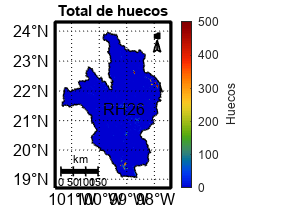


figure;
mapa_total_huecos(area_estudio==false)=nan;

m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,mapa_total_huecos,"Total de huecos",[],m_colmap('jet',100),"Huecos");
m_dibujar_kml(dir_data,"RH26",1,"k","RH26");

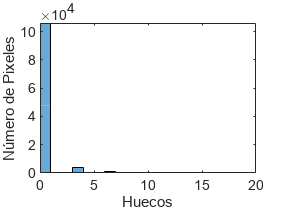


%HUECOS
serie = rmmissing( reshape(mapa_total_huecos,[],1));
tam_serie = length(serie);

figure;
histogram(serie,BinEdges=(0:20));
xlim([0 20]);
xlabel('Huecos');
ylabel('Número de Pixeles');

exportgraphics(gca,"img/histograma_tamaño_huecos_interp_2.png",'Resolution',300) 

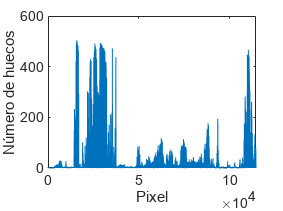



figure;
plot(serie);
xlim([0 tam_serie]);
xlabel('Pixel');
ylabel('Número de huecos');
%serie(serie>umbral_huecos)=nan;
%disp("% out HUECOS ("+umbral_huecos+"): "+ length(find(isnan(serie))) +" " );
%hline = refline([0 umbral_huecos]);
%hline.Color = 'r';
exportgraphics(gca,"img/numero_huecos_por_pixel_interp_2.png",'Resolution',300) 

### Analizando información de interpolacion 

Analizar el tamaño de los huecos

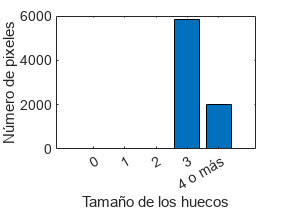

figure;
bar(num_nan);
xticklabels({'0','1','2','3','4 o más'});
xlabel('Tamaño de los huecos');
ylabel('Número de pixeles');

exportgraphics(gca,"img/tamaño_hueco_vs_no_pixeles_barra_interp_2.png",'Resolution',300) 

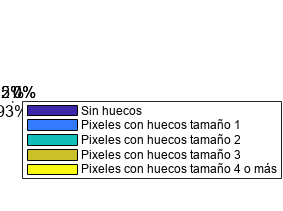



figure;
huecos = sum(num_nan(2:5));
num_nan(1) = tam_serie - huecos;
pie(num_nan);
labels = {'Sin huecos','Pixeles con huecos tamaño 1','Pixeles con huecos tamaño 2','Pixeles con huecos tamaño 3','Pixeles con huecos tamaño 4 o más'};
legend(labels,'Location','eastoutside','Orientation','vertical');
exportgraphics(gca,"img/tamaño_hueco_vs_no_pixeles_pie_o_interp_2.png",'Resolution',300) 

### Series menor numero de huecos

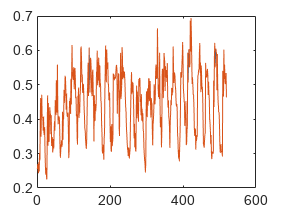

figure;

serie_original = reshape( arr_ndvi(idi_cm,idj_cm,:),[],1);
serie_interpol = reshape( arr_ndvi_inter(idi_cm,idj_cm,:),[],1);
serie_original_qa = reshape( arr_ndvi_qa(idi_cm,idj_cm,:),[],1);
serie_original(serie_original_qa ~= 0 & serie_original_qa ~= 1)=nan;

plot(1:filas,serie_interpol,1:filas,serie_original);

### Serie mayor numero de huecos

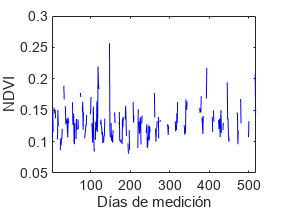


serie_original = reshape( arr_ndvi(idi_cma,idj_cma,:),[],1);
serie_nan = reshape( arr_ndvi_nan(idi_cma,idj_cma,:),[],1);

serie_interpol = reshape( arr_ndvi_inter(idi_cma,idj_cma,:),[],1);
serie_original_qa = reshape( arr_ndvi_qa(idi_cma,idj_cma,:),[],1);
%serie_original(serie_original_qa ~= 0 & serie_original_qa ~= 1)=nan;
% 
figure;
plot(1:filas,serie_nan,"b-");

xlim([1 519]);
xlabel('Días de medición');
ylabel('NDVI');
exportgraphics(gca,"img/muestra_serie_incompleta_interp_2_or.png",'Resolution',300) 

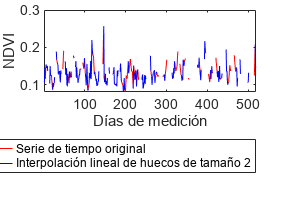


figure;
plot(1:filas,serie_interpol,"r-");

xlim([1 519]);
xlabel('Días de medición');
ylabel('NDVI');

hold on

plot(1:filas, serie_nan,"b-");
hold off
labels = {'Serie de tiempo original','Interpolación lineal de huecos de tamaño 2'};
legend(labels,'Location','southoutside','Orientation','vertical');

exportgraphics(gca,"img/muestra_serie_incompleta_interp_2.png",'Resolution',300) 


%serie_filtro = m_filtro_fourier(serie_interpol,serie_original);
% ff = fft(serie_original);
% figure;
% plot(abs(ff));
% 
% figure;
% plot(1:filas,serie_original,1:filas,serie_filtro);
% 
% 
% val_corr = corrcoef(serie_original,serie_filtro);
% disp("CORR: "+val_corr(1,2));

